# **Esercitzione n*6 - Stima di un modello di regressione multipla **

## Descrizione del problema

Il C-peptide e' co-secreto con l’insulina su base equimolare. Ha una cinetica lineare su un buon intervallo di concentrazioni e a differenza dell’insulina non e' estratto dal fegato prima della sua immissione nel torrente circolatorio. Pertanto il C-peptide e la sua cinetica giocano un ruolo fondamentale nello studio della secrezione insulinica. La cinetica e' solitamente descritta dal modello a due compartimenti. 

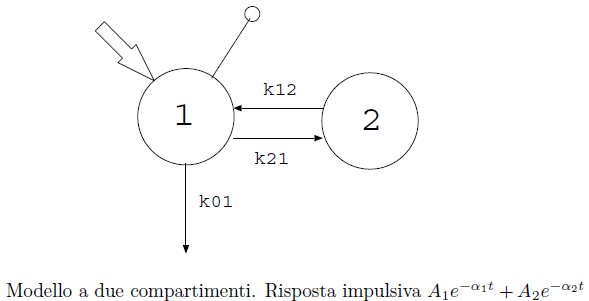

Per stimare i paramentri di questo modello negli anni ’80 si effettuavano esperimenti ingresso-uscita. Per evitare costosi esperimenti, negli anni 90 e' stato proposto da Van Cauter e coautori un nuovo approccio che sfrutta la “limitata” variabilita' della cinetica nei diversi soggetti, noti alcuni parametri antropometrici (covariate) quali sesso, stato di salute, dimensione corporea, eta', ecc. Per definire tale modello e' stato quindi condotto uno studio su oltre 200 soggetti di cui sono state raccolte alcune informazioni e di cui e' stata determinata la cinetica del C-peptide a seguito degli esperimenti ingresso-uscita precedentemente menzionati. L’analisi ha portato alla definzione di un modello di regressione lineare tra le covariate (regressori) e i parametri della cinetica (variabili dipendenti). In particolare, le potenziali covariate considerate sono:

- stato di salute (normali, obesi, diabetici)

- sesso

- eta'

- altezza

- peso

Dalle ultime due sono stati calcolati il BMI (body max index) la BSA (body surface area) rispettivamente come:

Invece di considerare direttamente i parametri della cinetica precedentemente citati ($k_{\mathrm{ij}}$ e $V$ o $A_i$ e $i$) sono stati considerati parametri derivati in modo da migliorare la relazione lineare tra covariate e parmetri in questione. In particolare, sono stati considerati:

- volume di distribuzione

- tempo di emivita corto

- tempo di emivita lungo

- fraction (rapporto tra i due esponenziali della risposta impulsiva A1/A1 +A2 dove A1 e A2 sono i coefficienti degli esponenziali relativi rispettivamente alle costanti di tempo corta e lunga).

clearvars;
close all;
clc;

## Descrizione del dataset

Il dataset e' costituito da una matrice in cui ogni riga contiene le informazioni relative ad ogni soggetto facente parte dello studio. Al suo interno sono contenute sia le possibili covariate (sesso, eta', ecc), sia le variabili dipendenti che caratterizzano la cinetica del C-peptide. Per comodita' si e' deciso di memorizzare i dati all'interno di una tabella. 

La covariata `Clinical` che rappresenta lo stato di salute e' codificata nel seguente modo: normal = 0, obese = 1, diab = 2. A sua volta la covariata `Sex `e' codificata come: M = 0, F = 1.

% Lettura del file "dati_vc.m"
dati_vc;

% Memorizzazione dei dati in tabella
tSogg = table(dati(:,1),dati(:,2),dati(:,3),dati(:,4),dati(:,5),dati(:,6),dati(:,7),dati(:,8),dati(:,9),dati(:,10),dati(:,11), ...
              'VariableNames',{'Clinical','Sex','Age','Height','Weight','BMI','BSA','Volume','thShort','thLong','Frac'});
tSogg.Properties.VariableUnits = {'','','Anni','m','kg','kg/m^2','m^2','L','','',''};
              
% Stampa dei primi 5 soggetti dello studio
tSogg(1:5,:)

ans = 5×11 table
    Clinical    Sex    Age    Height    Weight    BMI     BSA     Volume    thShort    thLong     Frac 
    ________    ___    ___    ______    ______    ____    ____    ______    _______    ______    ______

       0         0     31      1.78      70.2     22.2    1.86    4.961     5.1844      35.89    0.7763
       0         0     21      1.85      84.4     24.1    2.07    5.143     4.3451     31.381    0.7729
       0         1     33      1.57      52.7     21.4    1.56    3.919     5.2698     31.973    0.7048
       0         1     23      1.63      53.4     20.1    1.56    3.539     5.5016     3